%% Final 10-Feature Bandpower SVM
% This script:
% 1. Loads the 7-channel EEG epochs
% 2. Extracts the original 14 mu and beta features
% 3. Keeps only the previously selected 10 features
% 4. Trains and tests a linear SVM

clear;
close all;
clc;

%% Step 1: Set project path

basePath = '/Users/kandulasatwika/Desktop/400_BCI_MATLAB';


%% Step 2: Load the seven-channel epoch data

load(fullfile(basePath, 'Outputs', 'Filtered data', ...
    'combined_epochs_7channels.mat'));

disp('Seven-channel EEG epochs loaded.');

Seven-channel EEG epochs loaded.



disp(['Left data shape:  ', mat2str(size(all_left))]);

Left data shape:  [7 640 230]


disp(['Right data shape: ', mat2str(size(all_right))]);

Right data shape: [7 640 220]


disp(['Rest data shape:  ', mat2str(size(all_rest))]);

Rest data shape:  [7 640 420]




%% Step 3: Load the previously selected 10 features

% This file was created by the previous feature-selection script.
% We only load the final selected feature indices and names.
% No ranking is performed in this script.

load(fullfile(basePath, 'Outputs', ...
    'reduced_feature_svm_model.mat'), ...
    'selectedFeatureIndices', ...
    'selectedFeatureNames');

disp('Selected 10 features:');

Selected 10 features:


disp(selectedFeatureNames');

    "FC4_beta"
    "CP3_beta"
    "FC4_mu"
    "C4_mu"
    "C3_beta"
    "CP4_beta"
    "C3_mu"
    "FC3_mu"
    "CP4_mu"
    "CP3_mu"




disp('Selected feature column numbers:');

Selected feature column numbers:


disp(selectedFeatureIndices);

    10
     6
     9
    11
     4
    14
     3
     1
    13
     5





%% Step 4: Balance the three classes

% Find the smallest number of epochs among the three classes.

numberOfEpochs = min([size(all_left,3), ...
                      size(all_right,3), ...
                      size(all_rest,3)]);

disp(['Epochs used per class: ', ...
    num2str(numberOfEpochs)]);

Epochs used per class: 220



% Use the same random selection every time.
rng(42);

leftEpochIndices = randperm( ...
    size(all_left,3), numberOfEpochs);

rightEpochIndices = randperm( ...
    size(all_right,3), numberOfEpochs);

restEpochIndices = randperm( ...
    size(all_rest,3), numberOfEpochs);

% Select balanced epochs.
leftData = all_left(:,:,leftEpochIndices);

rightData = all_right(:,:,rightEpochIndices);

restData = all_rest(:,:,restEpochIndices);


%% Step 5: Extract all 14 mu and beta features

% Each of the seven channels produces:
%
% 1 mu feature
% 1 beta feature
%
% Total:
% 7 channels × 2 frequency bands = 14 features

leftFeatures14 = extract_motor_bandpower( ...
    leftData, samplingRate);

rightFeatures14 = extract_motor_bandpower( ...
    rightData, samplingRate);

restFeatures14 = extract_motor_bandpower( ...
    restData, samplingRate);

disp(['Original left feature shape:  ', ...
    mat2str(size(leftFeatures14))]);

Original left feature shape:  [220 14]



disp(['Original right feature shape: ', ...
    mat2str(size(rightFeatures14))]);

Original right feature shape: [220 14]



disp(['Original rest feature shape:  ', ...
    mat2str(size(restFeatures14))]);

Original rest feature shape:  [220 14]




%% Step 6: Keep only the selected 10 features

leftFeatures10 = ...
    leftFeatures14(:,selectedFeatureIndices);

rightFeatures10 = ...
    rightFeatures14(:,selectedFeatureIndices);

restFeatures10 = ...
    restFeatures14(:,selectedFeatureIndices);

disp(['Reduced left feature shape:  ', ...
    mat2str(size(leftFeatures10))]);

Reduced left feature shape:  [220 10]



disp(['Reduced right feature shape: ', ...
    mat2str(size(rightFeatures10))]);

Reduced right feature shape: [220 10]



disp(['Reduced rest feature shape:  ', ...
    mat2str(size(restFeatures10))]);

Reduced rest feature shape:  [220 10]




%% Step 7: Combine the features

X = [leftFeatures10;
     rightFeatures10;
     restFeatures10];

% Create labels for each epoch.
Y = [repmat("LEFT", numberOfEpochs, 1);
     repmat("RIGHT", numberOfEpochs, 1);
     repmat("REST", numberOfEpochs, 1)];

Y = categorical(Y);

disp(['Final feature matrix shape: ', ...
    mat2str(size(X))]);

Final feature matrix shape: [660 10]



% The second value should be 10.
% Example:
% 669 × 10


%% Step 8: Split data into training and testing sets

% Use 80% for training and 20% for testing.

cv = cvpartition(Y, ...
    'HoldOut', 0.20);

trainingIndices = training(cv);

testingIndices = test(cv);

XTrain = X(trainingIndices,:);

YTrain = Y(trainingIndices);

XTest = X(testingIndices,:);

YTest = Y(testingIndices);

disp(['Training samples: ', ...
    num2str(size(XTrain,1))]);

Training samples: 528



disp(['Testing samples: ', ...
    num2str(size(XTest,1))]);

Testing samples: 132




%% Step 9: Create the linear SVM

% Linear SVM is used because its behaviour is easier
% to understand than a nonlinear SVM.

svmTemplate = templateSVM( ...
    'KernelFunction', 'linear', ...
    'Standardize', true);

svmModel10Features = fitcecoc( ...
    XTrain, ...
    YTrain, ...
    'Learners', svmTemplate, ...
    'Coding', 'onevsone');

disp('10-feature linear SVM trained successfully.');

10-feature linear SVM trained successfully.




%% Step 10: Test the model

predictedLabels = predict( ...
    svmModel10Features, XTest);

accuracy10Features = mean( ...
    predictedLabels == YTest) * 100;

fprintf('\n10-feature SVM accuracy: %.2f%%\n', ...
    accuracy10Features);


10-feature SVM accuracy: 46.97%


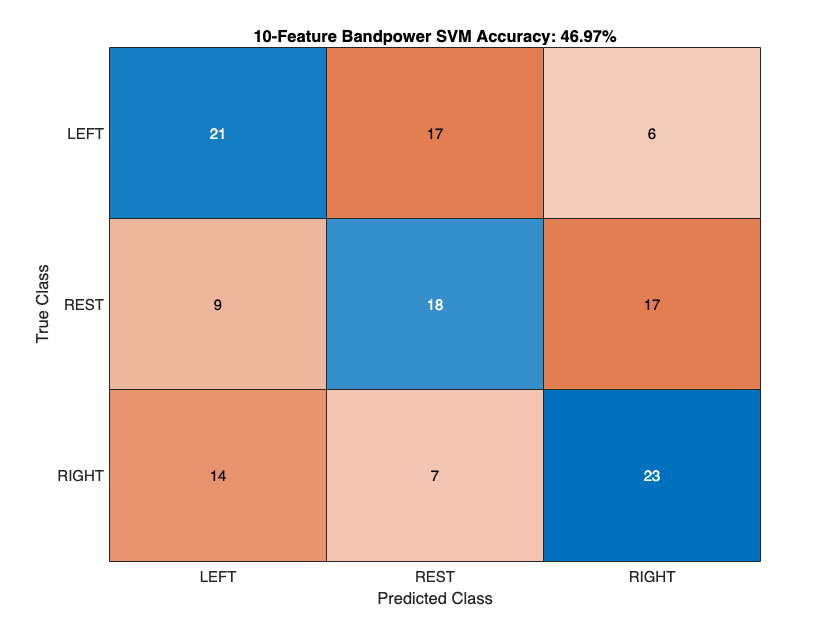



%% Step 11: Display the confusion matrix

figure;

confusionchart(YTest, predictedLabels);

title(['10-Feature Bandpower SVM Accuracy: ', ...
    num2str(accuracy10Features, '%.2f'), '%']);



%% Step 12: Save the final model

save(fullfile(basePath, 'Outputs', ...
    'final_10_feature_svm_model.mat'), ...
    'svmModel10Features', ...
    'accuracy10Features', ...
    'selectedFeatureIndices', ...
    'selectedFeatureNames', ...
    'selectedChannels', ...
    'samplingRate');

disp('Final 10-feature SVM model saved successfully.');

Final 10-feature SVM model saved successfully.




%% Local Function: Extract Mu and Beta Bandpower


function features = extract_motor_bandpower(data, samplingRate)

    % Input data shape:
    % channels × time points × epochs

    numberOfChannels = size(data,1);

    numberOfEpochs = size(data,3);

    % Two features per channel:
    % mu power and beta power.

    numberOfFeatures = numberOfChannels * 2;

    features = zeros( ...
        numberOfEpochs, numberOfFeatures);

    for e = 1:numberOfEpochs

        featurePosition = 1;

        for c = 1:numberOfChannels

            % Get one EEG signal from one channel
            % and one epoch.

            signal = double(data(c,:,e));

            % Calculate the power spectral density.

            [powerSpectrum, frequencies] = ...
                pwelch(signal, [], [], [], samplingRate);

            % Mu-band power from 8 to 12 Hz.

            muPower = mean( ...
                powerSpectrum( ...
                frequencies >= 8 & ...
                frequencies <= 12));

            % Beta-band power from 13 to 30 Hz.

            betaPower = mean( ...
                powerSpectrum( ...
                frequencies >= 13 & ...
                frequencies <= 30));

            % Store mu power.

            features(e,featurePosition) = ...
                log10(muPower + eps);

            % Store beta power.

            features(e,featurePosition + 1) = ...
                log10(betaPower + eps);

            featurePosition = ...
                featurePosition + 2;

        end

    end

end